# Introduction to common tasks

- Read data from different sources

- Set up the components for a reduced-form VAR model

- Estimate a reduced-form VAR model

- Run common tasks with reduced-form VAR model

- Set up the components for a structural identification of a VAR model

- Identify a structural VAR model from its original reduced form

- Run common tasks with structural VAR model

- Use multiple VAR models (objects) at the same time

- Use basic visualization tools

## Housekeeping


clear
close all
rehash path

addpath ../sandbox
addpath ../bear


## Convenience functions

These functions will be used when manipulating some of the output tables


percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

firstFunc = @(x) x(:, 1, :, :, :);

medianFunc = @(x) median(x, 2);

flatFunc = @(x) x(:, :);

defaultColors = get(0, "defaultAxesColorOrder");

configStruct = json.read("testConfig.json");
config = bear6.Config(configStruct);

config

config =   Config with properties:

              DataSource_Format: "CSV"
            DataSource_FilePath: "exampleData.csv"
              Tasks_Percentiles: {[1]  '5 50 95'  []  []}
          Tasks_ParameterTables: {[0]  'output/parameters.csv'  []  []}
     Tasks_AsymptoticMeanTables: {[0]  'output/asymptoticMeans.csv'  []  []}
        Tasks_ResidualEstimates: {[1]  'output/residualEstimates.csv'  []  []}
    Tasks_UnconditionalForecast: {[1]  'output/unconditionalForecast.csv'  '2010-Q1'  '2014-Q2'}
           Tasks_ShockEstimates: {[1]  'output/shockEstimates.csv'  []  []}
           Tasks_ShockResponses: {[1]  'output/shockResponses.csv'  []  []}
      Tasks_ConditionalForecast: {[0]  'output/unconditionalForecast.csv'  '2010-Q1'  '2014-Q2'}
              Tasks_SaveResults: {[1]  'output/results.mat'  []  []}
               Tasks_SaveConfig: {[1]  'output/config.json'  []  []}
                     Meta_Units:

## Reading data

- CSV

- Excel

- MAT file


inputTbx = tablex.fromCsv("exampleData.csv");

inputTbx2 = tablex.fromXls("exampleData.xlsx", sheet="input");

inputTbx, inputTbx2

inputTbx = 164×4 timetable
     Time      DOM_GDP     DOM_CPI     STN      Oil 
    _______    ________    _______    _____    _____

    1974-Q1    -0.44941    7.3837      9.32      4.6
    1974-Q2     0.35414    8.0729     11.25     15.5
    1974-Q3     -1.5423    8.3498     12.09       13
    1974-Q4     -1.1138    8.4424      9.35     11.5
    1975-Q1     -2.5888    7.9145       6.3     11.7
    1975-Q2    -0.85139     6.337      5.42     11.5
    1975-Q3       1.195    5.2976      6.16     11.4
    1975-Q4      3.7458    5.0088      5.41     11.5
    1976-Q1      5.2095    4.9506      4.83     11.6
    1976-Q2      4.3245    3.8559       5.2     1

inputTbx2 = 164×4 timetable
     Time      DOM_GDP     DOM_CPI     STN      Oil 
    _______    ________    _______    _____    _____

    1974-Q1    -0.44941    7.3837      9.32      4.6
    1974-Q2     0.35414    8.0729     11.25     15.5
    1974-Q3     -1.5423    8.3498     12.09       13
    1974-Q4     -1.1138    8.4424      9.35     11.5
    1975-Q1     -2.5888    7.9145       6.3     11.7
    1975-Q2    -0.85139     6.337      5.42     11.5
    1975-Q3       1.195    5.2976      6.16     11.4
    1975-Q4      3.7458    5.0088      5.41     11.5
    1976-Q1      5.2095    4.9506      4.83     11.6
    1976-Q2      4.3245    3.8559       5.2     

## Setting up components for reduced-form VAR model 

- Meta information

- Data holder

- Estimator

- Dummy observations

- Transformer


estimStart = datex.q(1975,1);
estimEnd = datex.q(2014,4);
estimSpan = datex.span(estimStart, estimEnd);
estimSpan

estimSpan = 1×160 datetime array
   1975-Q1   1975-Q2   1975-Q3   1975-Q4   1976-Q1   1976-Q2   1976-Q3   1976-Q4   1977-Q1   1977-Q2   1977-Q3   1977-Q4   1978-Q1   1978-Q2   1978-Q3   1978-Q4   1979-Q1   1979-Q2   1979-Q3   1979-Q4   1980-Q1   1980-Q2   1980-Q3   1980-Q4   1981-Q1   1981-Q2   1981-Q3   1981-Q4   1982-Q1   1982-Q2   1982-Q3   1982-Q4   1983-Q1   1983-Q2   1983-Q3   1983-Q4   1984-Q1   1984-Q2   1984-Q3   1984-Q4   1985-Q1   1985-Q2   1985-Q3   1985-Q4   1986-Q1   1986-Q2   1986-Q3   1986-Q4   1987-Q1   1987-Q2   1987-Q3   1987-Q4   1988-Q1   1988-Q2   1988-Q3   1988-Q4   1989-Q1   1989-Q2   1989-Q3   1989-Q4   1990-Q1   1990-Q2   1990-Q3   1990-Q4   1991-Q1   1991-Q2   1991-Q3   1991-Q4   1992-Q1   1992-Q2   1992-Q3   1992-Q4   1993-Q1   1993-Q2   1993-Q3   1993-Q4   1994-Q1   1994-Q2   1994-Q3   1994-Q4   1995-Q1   1995-Q2   1995-Q3   1995-Q4   1996-Q1   1996-Q2   1996-Q3   1996-Q4   1997-Q1   1997-Q2   1997-Q3   1997-Q4   1998-Q1   1998-Q2   1998-Q3   1998-Q4   1999


meta = model.Meta( ...
    endogenous=["DOM_GDP", "DOM_CPI", "STN"], ...
    units="", ...
    exogenous="Oil", ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=12, ...
    shockConcepts=["DEM", "SUP", "POL"] ...
);

meta

meta =   Meta with properties:

       EndogenousConcepts: ["DOM_GDP"    "DOM_CPI"    "STN"]
                    Units: ""
           ExogenousNames: "Oil"
           ReducibleNames: [1×0 string]
           ResidualPrefix: "resid"
                    Order: 4
             HasIntercept: 1
               NumFactors: 0
            ShockConcepts: ["DEM"    "SUP"    "POL"]
    IdentificationHorizon: 12
            HasCrossUnits: 0
                ShortSpan: [1975-Q1    1975-Q2    1975-Q3    1975-Q4    1976-Q1    1976-Q2    1976-Q3    1976-Q4    1977-Q1    1977-Q2    1977-Q3    1977-Q4    1978-Q1    1978-Q2    1978-Q3    1978-Q4    1979-Q1    1979-Q2    …    ] (1×160 datetime)
                SEPARATOR: "_"
               ShortStart: 1975-Q1
                 ShortEnd: 2014-Q4
          EndogenousNames: ["DOM_GDP"    "DOM_CPI"    "STN"]
            ResidualNames: ["resid_DOM_GDP"    "resid_DOM_CPI"    "resid_STN"]
         


dataH = model.DataHolder(meta, inputTbx);

estimatorR = estimator.NormalWishart( ...
    meta ...
    ... config.Estimator_Settings{:} ...
);

estimatorR

estimatorR =   NormalWishart with properties:

           DescriptionUX: "BVAR with Normal-Wishart prior"
          CanHaveDummies: 1
       CanHaveReducibles: 0
           HasCrossUnits: 0
                Settings: [1×1 estimator.settings.NormalWishart]
                 Sampler: []
           SampleCounter: 0
           HistoryDrawer: []
     UnconditionalDrawer: []
       ConditionalDrawer: []
    IdentificationDrawer: []
         BeenInitialized: 0
          ShortClassName: 'NormalWishart'



% estimatorR2 = estimator.GeneralTV(meta, Burnin=100);
% estimatorR2.Settings

minnesotaD = dummies.Minnesota(exogenousLambda=30);

modelR = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR ...
    , dummies={minnesotaD} ...
    , stabilityThreshold=Inf ...
);

modelR

modelR =   ReducedForm with properties:

                        Meta: [1×1 model.Meta]
                  DataHolder: [1×1 model.DataHolder]
                     Dummies: {[1×1 dummies.Minnesota]}
                   Estimator: [1×1 estimator.NormalWishart]
                  Presampled: {1×0 cell}
               ExogenousMean: [1×0 double]
    StabilityThresholdString: "Inf"
                  HasDummies: 1
                  NumDummies: 1
                     Sampler: []
        IdentificationDrawer: []
               HistoryDrawer: []
           ConditionalDrawer: []
         UnconditionalDrawer: []
               SampleCounter: 0
            CandidateCounter: NaN
               NumPresampled: 0


## Initializing reduced-form VAR model

The initialization step precalculates all the values needed for running a posterior simulator, creates the following function handles (accessible as properties of the reduced-form objec):

#### `.Sampler`

A function returning one sample from the posterior distribution

#### `.IdentificationDrawer`

A function taking one sample and returning a sequence (cell array) of VAR system matrices `A`, `C` and a fixed covariance matrix `Sigma` used for calculating shock responses. This sequence is generated only once for each sample and cached within the model object.

#### `.HistoryDrawer`

A function taking one sample and returning a sequence (cell array) of `A`, `C`, and `Sigma` matrices with their historical estimates (in time-varying models) or simply their estimates repeated the corresponding number of times.

#### `.UnconditionalDrawer`

A function taking one sample, a start date (index), and a forecast horizon lenght, and generates a sequence (cell array) of `A`, `C`, and `Sigma` matrices meant for calculating an unconditional forecast on the given forecast span. This sequence is not cached: 

- for time-invariant models, the function simply returns a sequence of fixed system matrices;

- for time-varying models, the function generates (randomly) using the estimated probabilistic assumptions about the time evolution of the model parameters.

#### `.ConditionalDrawer`

Same as `.UnconditionalDrawer` but for conditional forecasts.


modelR.initialize();

modelR

modelR =   ReducedForm with properties:

                        Meta: [1×1 model.Meta]
                  DataHolder: [1×1 model.DataHolder]
                     Dummies: {[1×1 dummies.Minnesota]}
                   Estimator: [1×1 estimator.NormalWishart]
                  Presampled: {1×0 cell}
               ExogenousMean: 37.5719
    StabilityThresholdString: "Inf"
                  HasDummies: 1
                  NumDummies: 1
                     Sampler: @NormalWishart.initializeSampler/sampler
        IdentificationDrawer: @PlainDrawersMixin.createDrawers/identificationDrawer
               HistoryDrawer: @(sample)drawer(sample,estimationHorizon)
           ConditionalDrawer: @(sample,start,horizon)drawer(sample,horizon)
         UnconditionalDrawer: @(sample,start,horizon)drawer(sample,horizon)
               SampleCounter: 0
            CandidateCounter: NaN
               NumPresampled: 0


## Presampling from posterior

Generate a specified number of samples from the posterior distributions. These samples are cached, and use in all of the subsequent calculations.


modelR.presample(100);

 Presampling model.ReducedForm [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




modelR

modelR =   ReducedForm with properties:

                        Meta: [1×1 model.Meta]
                  DataHolder: [1×1 model.DataHolder]
                     Dummies: {[1×1 dummies.Minnesota]}
                   Estimator: [1×1 estimator.NormalWishart]
                  Presampled: {1×100 cell}
               ExogenousMean: 37.5719
    StabilityThresholdString: "Inf"
                  HasDummies: 1
                  NumDummies: 1
                     Sampler: @NormalWishart.initializeSampler/sampler
        IdentificationDrawer: @PlainDrawersMixin.createDrawers/identificationDrawer
               HistoryDrawer: @(sample)drawer(sample,estimationHorizon)
           ConditionalDrawer: @(sample,start,horizon)drawer(sample,horizon)
         UnconditionalDrawer: @(sample,start,horizon)drawer(sample,horizon)
               SampleCounter: 100
            CandidateCounter: NaN
               NumPresampled: 100


## Using reduced-form VAR model

Using the estimated reduced-form model, run the following calculations:

- Estimate the historical reduals (one set of residuals for each sample)

- Run an unconditional forecast (within historical range)


residTbx = modelR.estimateResiduals();


fcastStart = datex.shift(modelR.Meta.EstimationEnd, -10);
fcastEnd = datex.shift(modelR.Meta.EstimationEnd, 0);

fcastStart = datetime
   2012-Q2


fcastEnd = datetime
   2014-Q4


fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd


fcastTbx = 15×6 timetable
     Time        DOM_GDP         DOM_CPI           STN         resid_DOM_GDP    resid_DOM_CPI     resid_STN  
    _______    ____________    ____________    ____________    _____________    _____________    ____________

    2011-Q2    1×100 double    1×100 double    1×100 double    1×100 double     1×100 double     1×100 double
    2011-Q3    1×100 double    1×100 double    1×100 double    1×100 double     1×100 double     1×100 double
    2011-Q4    1×100 double    1×100 double    1×100 double    1×100 double     1×100 double     1×100 double
    2012-Q1    1×100 double    1×100 double    1×100 double    1×100 double     1×100 double     1×100 double
    

fcastTbx = modelR.forecast(fcastSpan);

fcastTbx

fcastPrctileTbx = 15×6 timetable
     Time                  DOM_GDP                               DOM_CPI                                STN                            resid_DOM_GDP                        resid_DOM_CPI                           resid_STN             
    _______    ________________________________    ___________________________________    _______________________________    _________________________________    __________________________________    __________________________________

    2011-Q2     0.96531     0.96531     0.96531       2.9986       2.9986       2.9986       0.09        0.09        0.09        NaN          NaN          NaN         NaN          NaN          NaN         NaN          NaN          NaN
    <s

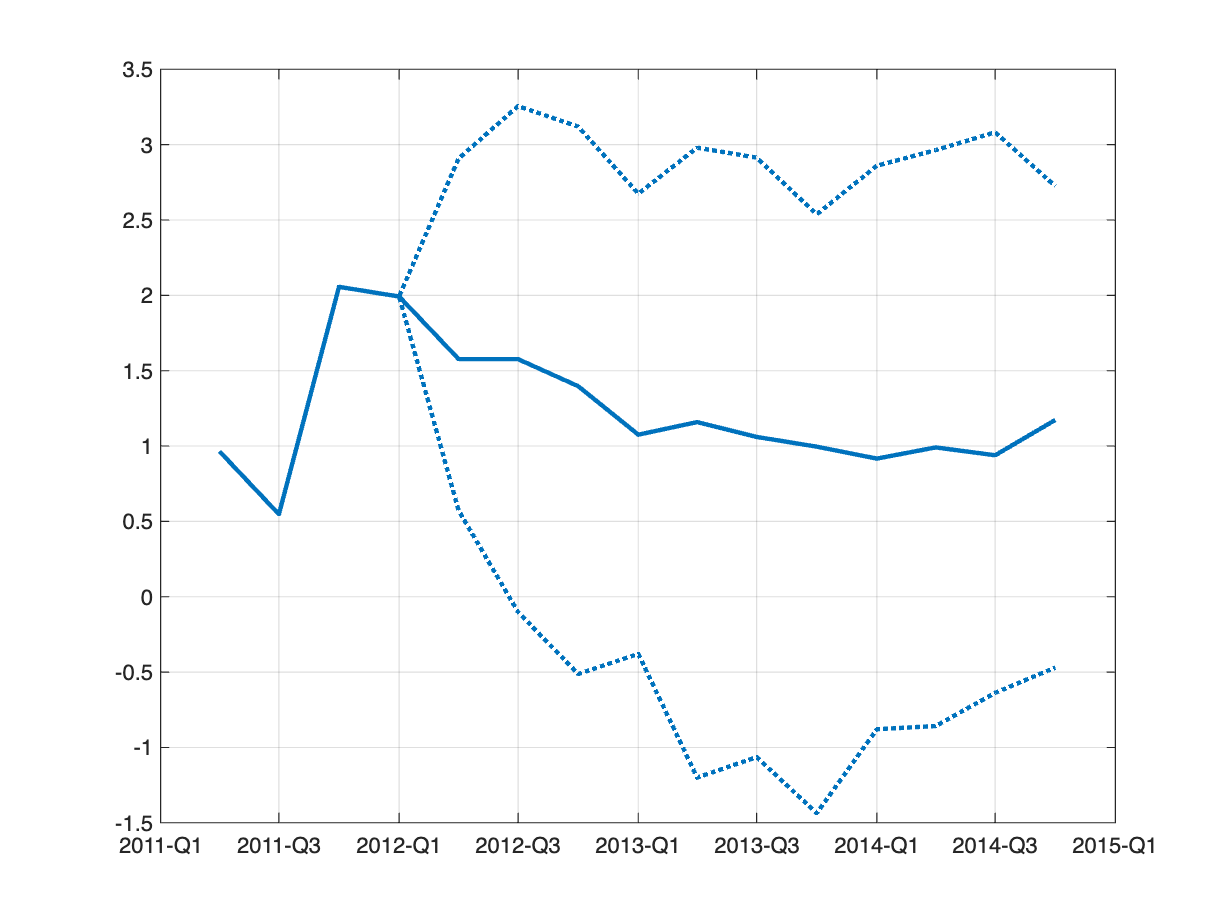


fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx

tablex.plot( ...

    fcastPrctileTbx, "DOM_GDP", ...
    plotSettings={"color", defaultColors(1, :), {"lineStyle"}, {":"; "-"; ":"}} ...
);


## Setting up components for structural VAR


id = identifier.Cholesky();

modelS = model.Structural( ...
    reducedForm=modelR, ...
    identifier=id ...
);

modelS

modelS =   Structural with properties:

             ReducedForm: [1×1 model.ReducedForm]
              Identifier: [1×1 identifier.Cholesky]
              Presampled: []
       PresampledCounter: 0
                    Meta: [1×1 model.Meta]
              DataHolder: [1×1 model.DataHolder]
                 Sampler: []
           SampleCounter: 0
        CandidateCounter: 0
    IdentificationDrawer: @PlainDrawersMixin.createDrawers/identificationDrawer
           HistoryDrawer: @(sample)drawer(sample,estimationHorizon)
       ConditionalDrawer: @(sample,start,horizon)drawer(sample,horizon)
     UnconditionalDrawer: @(sample,start,horizon)drawer(sample,horizon)
           NumPresampled: 0


## Identifying structural VAR


modelS.initialize();

modelS

modelS =   Structural with properties:

             ReducedForm: [1×1 model.ReducedForm]
              Identifier: [1×1 identifier.Cholesky]
              Presampled: []
       PresampledCounter: 0
                    Meta: [1×1 model.Meta]
              DataHolder: [1×1 model.DataHolder]
                 Sampler: @Cholesky.initializeSampler/samplerS
           SampleCounter: 0
        CandidateCounter: 0
    IdentificationDrawer: @PlainDrawersMixin.createDrawers/identificationDrawer
           HistoryDrawer: @(sample)drawer(sample,estimationHorizon)
       ConditionalDrawer: @(sample,start,horizon)drawer(sample,horizon)
     UnconditionalDrawer: @(sample,start,horizon)drawer(sample,horizon)
           NumPresampled: 0



info = modelS.presample(100);

 Presampling model.Structural [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




info

info = struct with fields:
                SampleCount: 100
             CandidateCount: 100
    SuccessfulCandidateRate: 1
       SuccessfulSampleRate: 1


## Using structural VAR

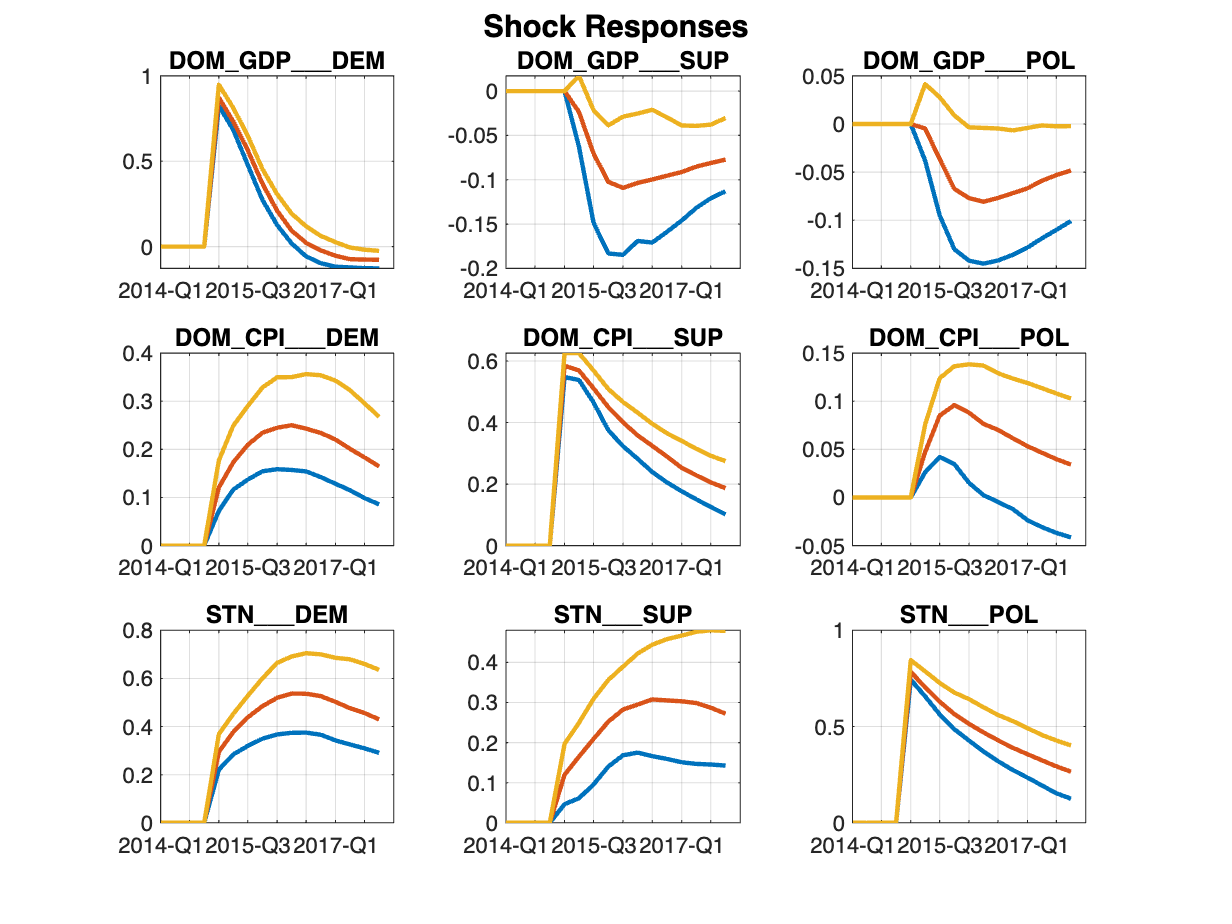


fcastTbx = modelS.forecast(fcastSpan);

residTbx = modelS.estimateResiduals();

shkTbx = modelS.estimateShocks();

simTbx = modelS.simulateResponses();
simPctTbx = tablex.apply(simTbx, prctileFunc);
simPctTbx = tablex.flatten(simPctTbx);

ch = visual.Chartpack( ...
    span=tablex.span(simPctTbx), ...
    namesToPlot=tablex.names(simPctTbx), ...
    captions="Shock Responses" ...
);
ch.plot(simPctTbx);

## Structural identification with general restrictions



testStrings = [
    "abs($SHKRESP(1, 'DOM_GDP', 'POL')) > 0"
    "$SHKEST('2014-Q1', 'DEM') > 0.1"
    "$SHKCONT('2010-Q3', 'DOM_CPI', 'SUP') > 0"
]

testStrings = 3×1 string array
    "abs($SHKRESP(1, 'DOM_GDP', 'POL')) > 0"
    "$SHKEST('2014-Q1', 'DEM') > 0.1"
    "$SHKCONT('2010-Q3', 'DOM_CPI', 'SUP') > 0"



id2 = identifier.Verifiables(testStrings, maxCandidates=50);

modelS = model.Structural( ...
    reducedForm=modelR, ...
    identifier=id2 ...
);


modelS.initialize()
info = modelS.presample(100);

 Presampling model.Structural [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



info

info = struct with fields:
                SampleCount: 103
             CandidateCount: 702
    SuccessfulCandidateRate: 0.1425
       SuccessfulSampleRate: 0.9709


## Using structural VAR



shkTbx = modelS.estimateShocks();
simTbx = modelS.simulateResponses();

contTbx = modelS.breakdown();
fcastTbx = modelS.forecast(fcastSpan);
fevdTbx = modelS.calculateFEVD();

tablex.getHigherDims(contTbx)

ans = 1×1 cell array
    {["DEM"    "SUP"    "POL"    "Exogenous"    "Initials"]}


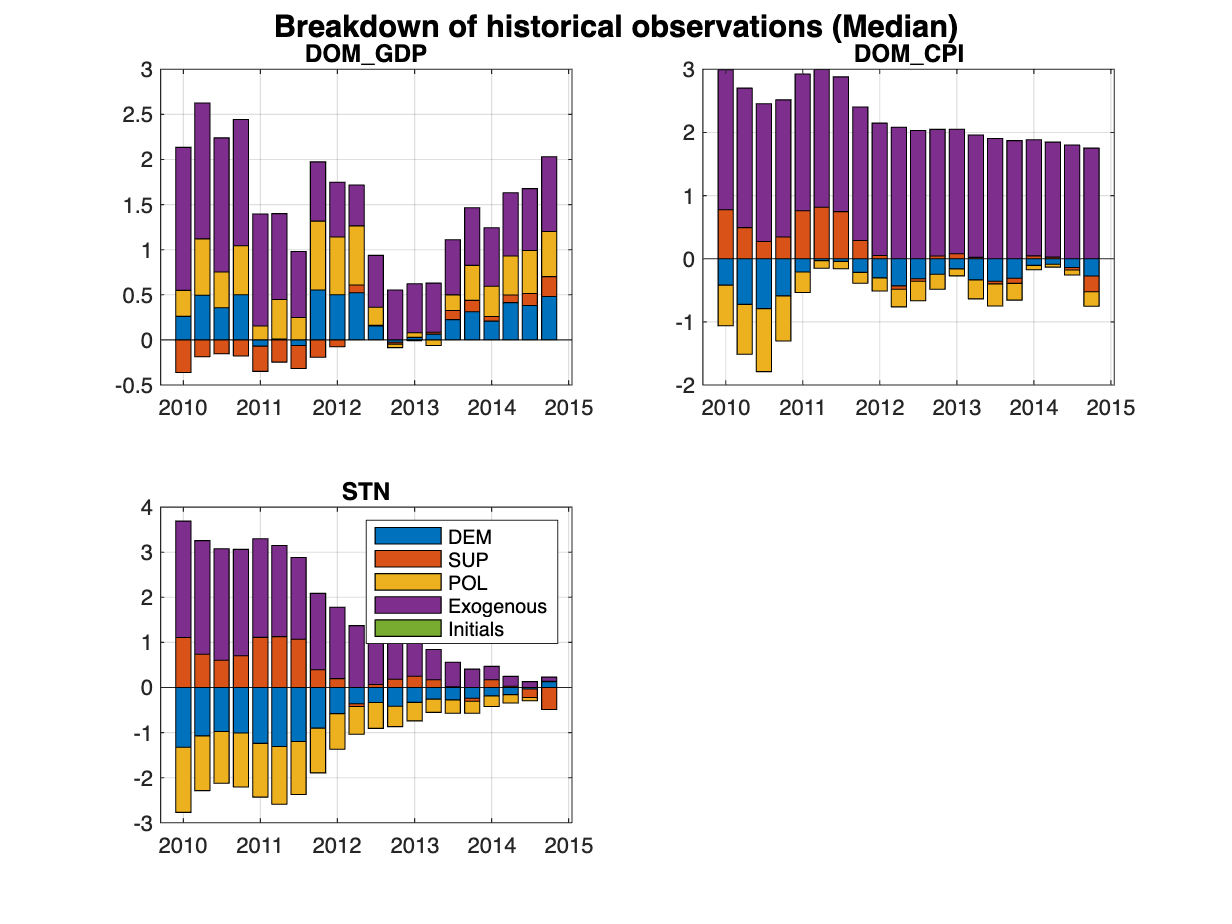


contMedTbx = tablex.apply(contTbx, medianFunc);
contMedTbx = tablex.apply(contMedTbx, flatFunc);

ch = visual.Chartpack( ...
    span=datex.span("2010-Q1", "2014-Q4"), ...
    namesToPlot=modelS.Meta.EndogenousNames, ...
    captions="Breakdown of historical observations (Median)", ...
    plotFunc=@bar ...
);
ch.plot(contMedTbx);
leg = tablex.getHigherDims(contMedTbx);
legend(leg{1});